# Análisis espacio-temporal de la Cuenca del Río Pánuco

import matlab.io.hdfeos.*;
clearvars -except study_area;

%directorio de datos
dir_data = "D:\DATA\";
modis_product = 'MOD13A2';
kml_file = "RH26";

% Cargar los datos en los arreglos
m_cargar_datos

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1078 archivos
>>>>> Obteniendo la zona de estudio
D:\DATA\MOD13A2\061\*.hdf
>>>>> Analizando 1078 archivos
>>>>> Obteniendo latitud y longitud
>>> Cargando área de estudio
>>> Área de estudio existente 1


## Filtrar información por meses

% Declaraciones
% Los años que se desean consultar
meses = 1:12;
anios = 2000:2022;

% Arreglo donde se almacenara el promedio de NDVI por año
tabla_promedio =zeros(length(anios),length(meses));
tabla_desvEst =zeros(length(anios),length(meses));

tabla_promedio_mj =zeros(length(anios),length(meses));
tabla_desvEst_mj =zeros(length(anios),length(meses));

%generar las etiquetas de año y estación
lbl_meses = ["Enero","Febrero","Marzo","Abril","Mayo","Junio","Julio","Agosto","Septiembre","Octubre","Noviembre","Diciembre"];
%lbl_meses = ["Enero","","","","","","","","","","",""];

lbl_ejex = string(1: length(anios)*length(meses));
a=1;
for i=anios
    for j=meses
        if j == 1 %|| j == 3 || j== 6 || j==9 
            lbl_ejex (a) = strcat( lbl_meses(j)," ",""+i);
        else
            lbl_ejex (a)="";
        end
        a=a+1;
    end
end

x=1;   
bp=waitbar(0,'Filtrando información'); 

for y= 1:length(anios)

    for m = 1:length(meses)
        tmp =  find(  info_hdf.anio == anios(y) & info_hdf.mes == meses(m)  );
    
        if( isempty (tmp))
            continue;
        end
        tabla_promedio(y,m) = mean(arr_ndvi (:,:,tmp),"all","omitnan");
        tabla_desvEst(y,m) = std(arr_ndvi (:,:,tmp),0,"all","omitnan");

        tabla_promedio_mj(y,m) = mean(arr_ndvi_mj (:,:,tmp),"all","omitnan");
        tabla_desvEst_mj(y,m) = std(arr_ndvi_mj (:,:,tmp),0,"all","omitnan");
        
    end
    waitbar(y/length(anios),bp,sprintf('Año: (%4d) ',anios(y)));

end
close(bp); 


### Usar los datos obtenidos para generar series de tiempo

Mostrar el promedio por mes de cada año

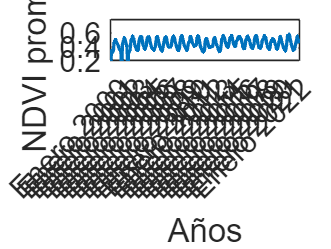

figure;

linea_tiempo_promedio = reshape(tabla_promedio',[],1);
linea_tiempo_promedio_mj = reshape(tabla_promedio_mj',[],1);

linea_tiempo_desv = reshape(tabla_desvEst',[],1);
linea_tiempo_desv_mj = reshape(tabla_desvEst_mj',[],1);

plot(linea_tiempo_promedio_mj,'LineWidth',2);
%title('NDVI promedio x estación');
xlabel('Años','FontSize',18);
xticks(1:length(linea_tiempo_promedio_mj));
xticklabels(lbl_ejex);
ylabel('NDVI promedio','FontSize',18);
xlim([0 (length(linea_tiempo_promedio_mj)+1)]);
ylim([0.2 0.8]);
xtickangle(45);
ax = gca;
ax.FontSize=18; 


%hold on
%plot(linea_tiempo_promedio_lf,'LineWidth',1,'LineStyle','--');
%plot(linea_tiempo_promedio_sgf,'LineWidth',2);
%hold off
% hold on
% 
% er=errorbar(1:length(linea_tiempo_promedio),linea_tiempo_promedio,linea_tiempo_desv); 
% er.Color = [0 0 0];                            
% er.LineStyle = 'none';  
% 
% hold off

% exportgraphics(gca,"img/new_g_promedio_x_año_mes_lt.png",'Resolution',300) 


## Mostrar promedios por meses

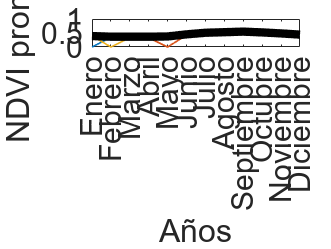

figure;
plot(1:12,tabla_promedio_mj,LineWidth=1);
xlabel('Años','FontSize',18);
ylabel('NDVI promedio','FontSize',18);
xticklabels(lbl_meses);
xticks(1:12);
ylim([0 1]);
xlim([1 12]);
prom = mean(tabla_promedio_mj);

hold on
plot(1:12,prom,"k",LineWidth=5);

hold off
 ax = gca;
 ax.FontSize=18; 

% exportgraphics(gca,"img/new_g_promedio_x_año_mes_lt_año.png",'Resolution',300) 


## Mostrar promedio por meses

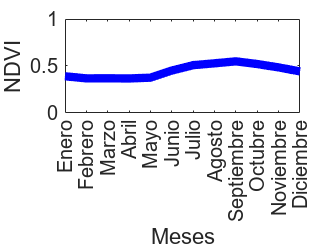

figure;
prom = mean(tabla_promedio_mj);
desv = mean(tabla_desvEst_mj);
plot(1:12,prom,"b",LineWidth=5);
xlabel('Meses','FontSize',18);
ylabel('NDVI','FontSize',18);
xticklabels(lbl_meses);
xticks(1:12);
ylim([0 1]);
xlim([1 12]);

% hold on
% er=errorbar(1:12,prom,desv); 
% er.Color = [0 0 0];                            
% er.LineStyle = 'none';  
% hold off

ax = gca;
ax.FontSize=12; 
exportgraphics(gca,"img/aet_promedio_x_año_mes.png",'Resolution',300);